DATA 17.02

        u1                  u2            

B    1        0            0        0

C    0.5     0            0        0

D    0.5    0            0.5      0     

E    0        0            1        0

F    1        0            0.5    0

B

B, C

B, F

B, F, D

close all;
clear;
clc;

dataA = readtable('dataRecorded\17_02\17_2_dataB.csv') 

dataA = 550×6 table
    time       y1           y2            y3            u1        u2
    ____    _________    _________    __________    __________    __

      0     0.0018466    0.0007048    -0.0007288    0.00010128    0 
      1     0.0018466    0.0007048    -0.0007288    0.00010128    0 
      2     0.0056738    0.0007048     -0.000564    0.00010128    0 
      3      0.013827    0.0007048     -6.96e-05    0.00010128    0 
      4      0.013827    0.0007048     0.0009192    0.00010128    0 
      5       0.02065    0.0010363     0.0020728    0.00010128    0 
      6      0.028304    0.0012021     0.0020728    0.00010128    0 
      7      0.033629    0.0013678     0.0030616    0.00010128    0 
      8       0.04145    0.0013678     0.0037208    0.00010128    0 
      9      0.0

noise = 1E-6;

x1A = [noise.* randn(5,1); dataA.y1];
x2A  = [noise.* randn(5,1); dataA.y2];
x3A  = [noise.* randn(5,1); dataA.y3];

u1A = dataA.u1;
u2A = dataA.u2;

lengthA = length(x1A)

lengthA = 555

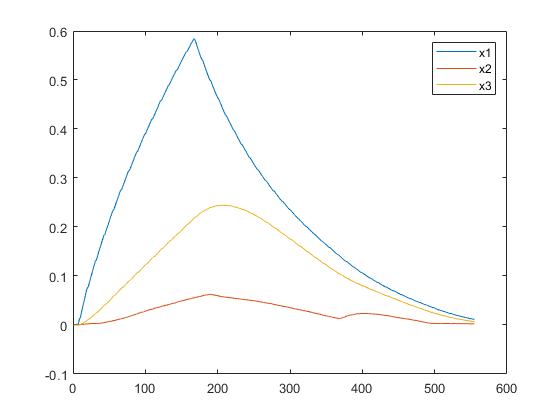


plot(x1A);
hold on;
plot(x2A);
plot(x3A);
hold off;
legend("x1",'x2','x3');

% 
% plot(u1A);
% hold on;
% plot(u2A);
% hold off;
% legend("u1",'u2');

DATA verarbeiten A

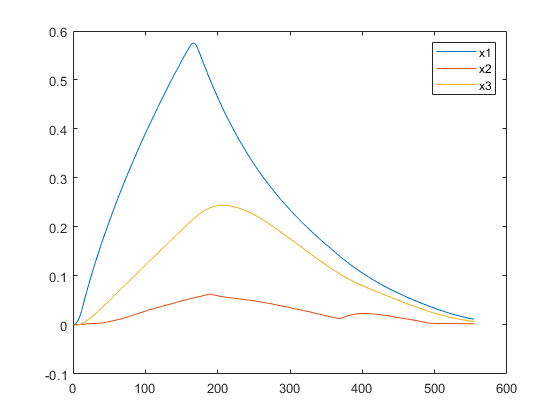

x1A = smoothdata(x1A,'gaussian',20);
x2A = smoothdata(x2A,'gaussian',5);
x3A = smoothdata(x3A,'gaussian',15);
dx1A = zeros(lengthA-1,1);
dx2A = dx1A;
dx3A = dx1A;

for i = 2 : lengthA
%    dx1(i-1) = smoothdata(x1(i)-x1(i-1),20,'gaussian');
%    dx2(i-1) = smoothdata(x2(i)-x2(i-1),'gaussian');
%    dx3(i-1) = smoothdata(x3(i)-x3(i-1),'gaussian');
    dx1A(i-1) = x1A(i)-x1A(i-1);
    dx2A(i-1) = x2A(i)-x2A(i-1);
    dx3A(i-1) = x3A(i)-x3A(i-1);
end
plot(x1A);
hold on;
plot(x2A);
plot(x3A);
hold off;
legend("x1",'x2','x3');

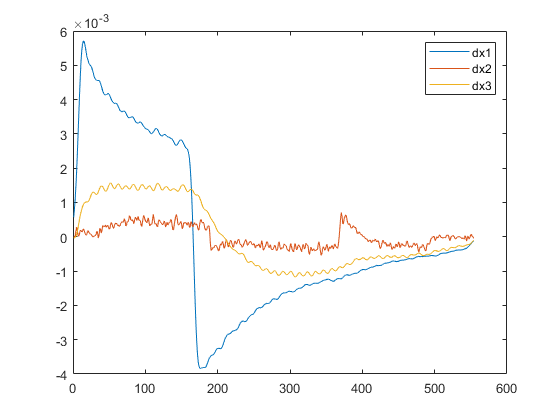


plot(dx1A);
hold on;
plot(dx2A);
plot(dx3A);
hold off;
legend("dx1",'dx2','dx3');

DATA B

dataB = readtable('dataRecorded\17_02\17_2_dataF.csv') 

dataB = 540×6 table
    time       y1           y2           y3            u1           u2    
    ____    _________    _________    _________    __________    _________

      0     0.0035106    0.0016994    0.0007544    0.00010128    5.064e-05
      1     0.0035106    0.0013678    0.0007544    0.00010128    5.064e-05
      2     0.0038434      0.00402    0.0007544    0.00010128    5.064e-05
      3      0.011498    0.0061749    0.0014136    0.00010128    5.064e-05
      4      0.018653    0.0078325     0.002732    0.00010128    5.064e-05
      5      0.025309    0.0078325    0.0047096    0.00010128    5.064e-05
      6      0.031632      0.01065     0.006028    0.00010128    5.064e-05
      7      0.038455     0.012142    0.0073464    0.00010128    5.064e-05
      8      0.044944    

noise = 1E-6;

x1B = [noise.* randn(5,1); dataB.y1];
x2B  = [noise.* randn(5,1); dataB.y2];
x3B  = [noise.* randn(5,1); dataB.y3];

u1B = dataB.u1;
u2B = dataB.u2;

lengthB = length(x1B)

lengthB = 545


%u1B(197:lengthB) = 0;

% plot(x1);
% hold on;
% plot(x2);
% plot(x3);
% hold off;
% legend("x1",'x2','x3');
% 
% plot(u1);
% hold on;
% plot(u2);
% hold off;
% legend("u1",'u2');

DATA verarbeiten B

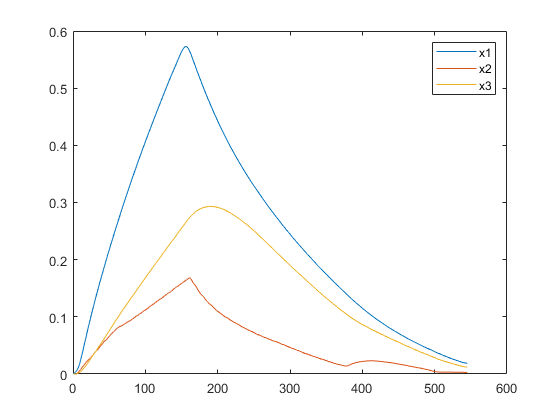

x1B = smoothdata(x1B,'gaussian',20);
x2B = smoothdata(x2B,'gaussian',5);
x3B = smoothdata(x3B,'gaussian',15);
dx1B = zeros(lengthB-1,1);
dx2B = dx1B;
dx3B = dx1B;

for i = 2 : lengthB
%    dx1(i-1) = smoothdata(x1(i)-x1(i-1),20,'gaussian');
%    dx2(i-1) = smoothdata(x2(i)-x2(i-1),'gaussian');
%    dx3(i-1) = smoothdata(x3(i)-x3(i-1),'gaussian');
    dx1B(i-1) = x1B(i)-x1B(i-1);
    dx2B(i-1) = x2B(i)-x2B(i-1);
    dx3B(i-1) = x3B(i)-x3B(i-1);
end
plot(x1B);
hold on;
plot(x2B);
plot(x3B);
hold off;
legend("x1",'x2','x3');

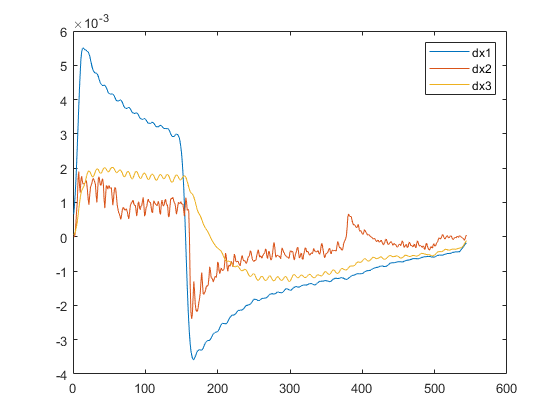


plot(dx1B);
hold on;
plot(dx2B);
plot(dx3B);
hold off;
legend("dx1",'dx2','dx3');

All DATA together

targetLength = 50;
divisions = 1;%3
divLength = targetLength / divisions;

x1 = zeros(targetLength,1); x2 = x1; x3 = x1; 
u1 = x1; u2 = x1;
dx1 = x1; dx2 = x1; dx3 = x1;

div1: A from 0 to max

length1 = lengthA;%162
div1 = floor(length1/divLength);
for i = 1 : divLength
    pos = (i-1)*div1 + 1;
    count  = i;
    x1(count) = x1A(pos);
    x2(count) = x2A(pos);
    x3(count) = x3A(pos);
    
    dx1(count) = dx1A(pos);
    dx2(count) = dx2A(pos);
    dx3(count) = dx3A(pos);
    
    u1(count) = u1A(pos);
    u2(count) = u2A(pos);
end


div2: B from 0 to max

% length2 = lengthB;
% div2 = floor(length2/divLength);
% for i = 1 : divLength
%     pos = (i-1)*div2 + 1;
%     count  = i + divLength;
%     x1(count) = x1B(pos);
%     x2(count) = x2B(pos);
%     x3(count) = x3B(pos);
%     
%     dx1(count) = dx1B(pos);
%     dx2(count) = dx2B(pos);
%     dx3(count) = dx3B(pos);
%     
%     u1(count) = u1B(pos);
%     u2(count) = u2B(pos);
% end

div3: A from max to zero

% length3Start = length1 + 1;
% length3End  = lengthA;
% 
% div3 = floor((length3End -length3Start)/divLength);
% for i = 1 : divLength
%     pos = (i-1)*div3 + length3Start;
%     count  = i + divLength; % * 2
%     x1(count) = x1A(pos);
%     x2(count) = x2A(pos);
%     x3(count) = x3A(pos);
%     
%     dx1(count) = dx1A(pos);
%     dx2(count) = dx2A(pos);
%     dx3(count) = dx3A(pos);
%     
%     u1(count) = u1A(pos);
%     u2(count) = u2A(pos);
% end

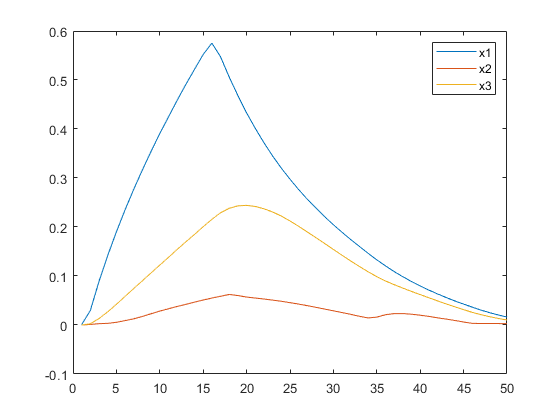

plot(x1);
hold on;
plot(x2);
plot(x3);
hold off;
legend("x1",'x2','x3');

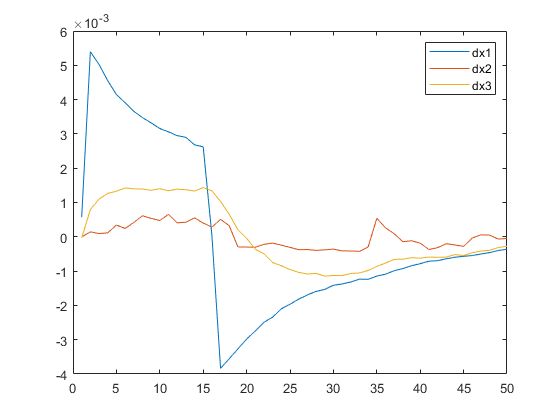


plot(dx1);
hold on;
plot(dx2);
plot(dx3);
hold off;
legend("dx1",'dx2','dx3');

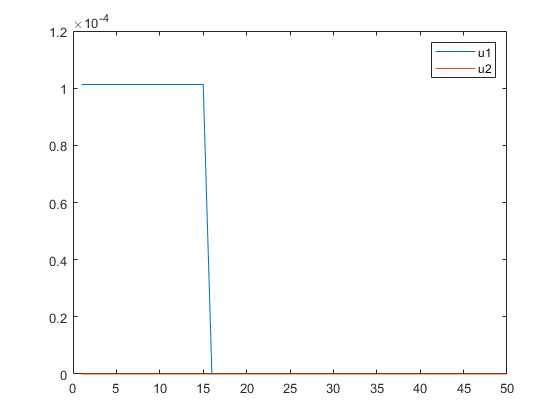



plot(u1);
hold on;
plot(u2);
hold off;
legend("u1",'u2');

% 

testData = table(x1,x2,x3,dx1,dx2,dx3,u1,u2);
save("dataOut/testData12.mat","testData");
writetable(testData,"dataOut/testData12.csv",'Delimiter',';');